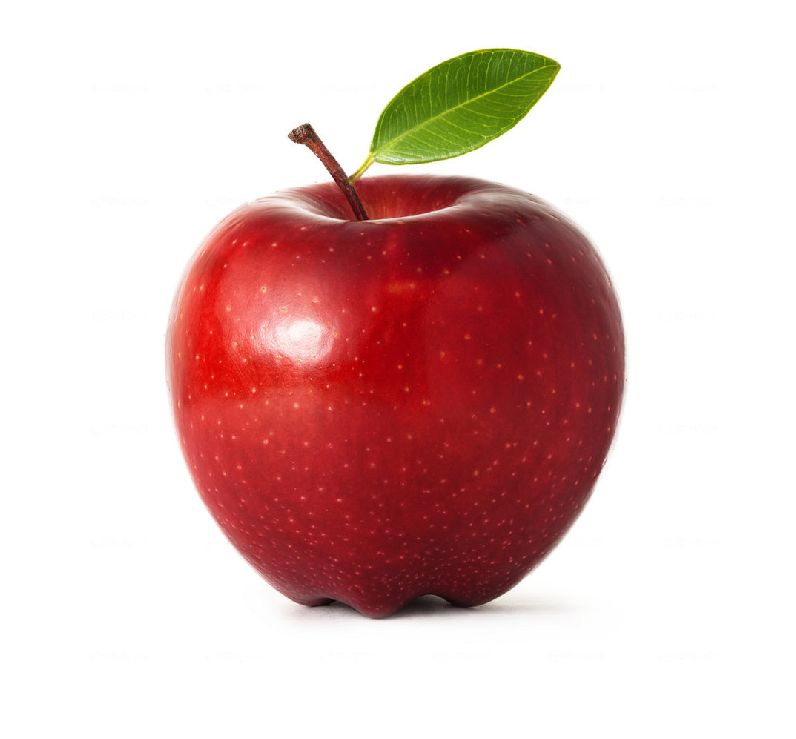

apel = imread("buah\buah1.jpg");
imshow(apel);

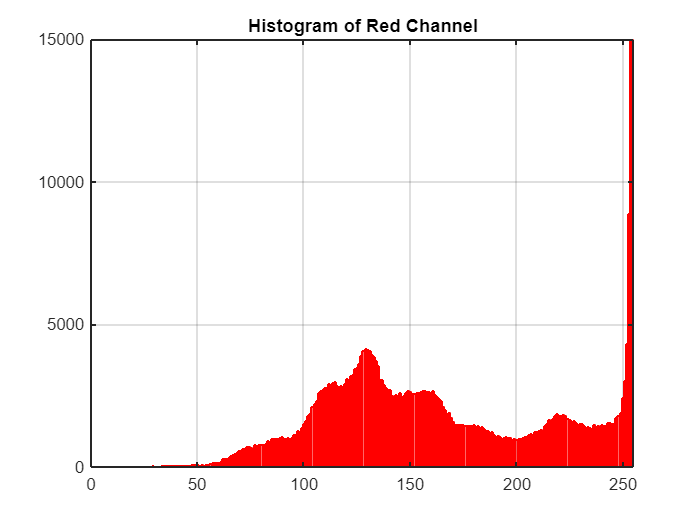

% RGB Features Extraction
R_stats = regionprops(apel_bw,R,'PixelValues','MeanIntensity',...
    'MaxIntensity','MinIntensity');
G_stats = regionprops(apel_bw,G,'PixelValues','MeanIntensity',...
    'MaxIntensity','MinIntensity');
B_stats = regionprops(apel_bw,B,'PixelValues','MeanIntensity',...
    'MaxIntensity','MinIntensity');
 
R_pix_val = R_stats.PixelValues;
G_pix_val = G_stats.PixelValues;
B_pix_val = B_stats.PixelValues;
 
figure,
histogram(R_pix_val,256,'FaceColor','r','EdgeColor','r')
set(gca,'XLim',[0 255])
set(gca,'YLim',[0 15000])
grid on
title('Histogram of Red Channel')

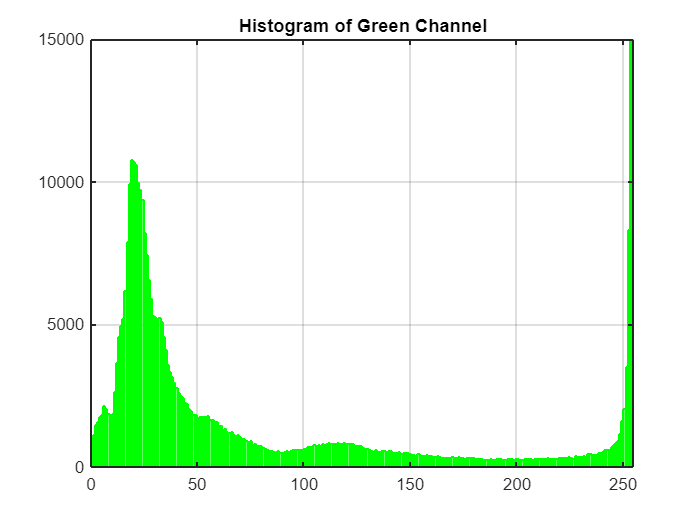

 
figure,
histogram(G_pix_val,256,'FaceColor','g','EdgeColor','g')
set(gca,'XLim',[0 255])
set(gca,'YLim',[0 15000])
grid on
title('Histogram of Green Channel')

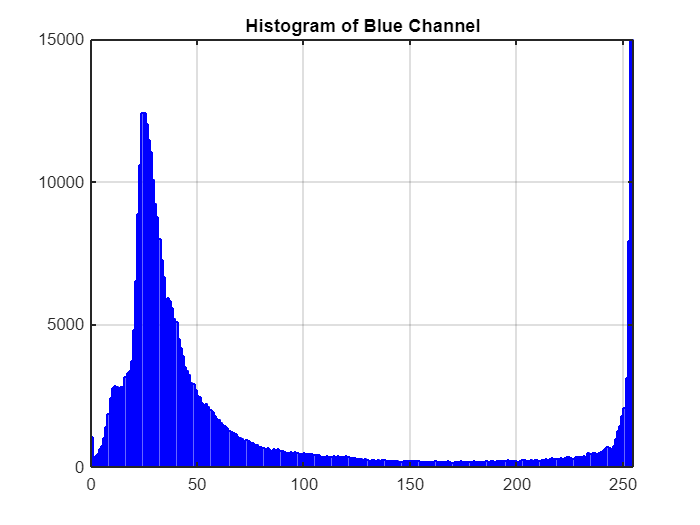

 
figure,
histogram(B_pix_val,256,'FaceColor','b','EdgeColor','b')
set(gca,'XLim',[0 255])
set(gca,'YLim',[0 15000])
grid on
title('Histogram of Blue Channel')

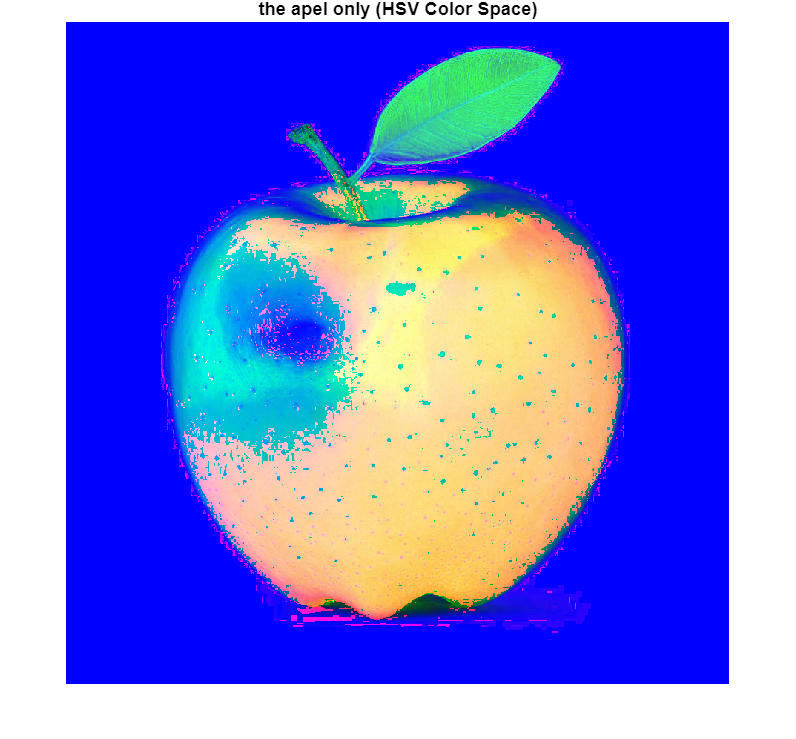

R_mean = R_stats.MeanIntensity;
G_mean = G_stats.MeanIntensity;
B_mean = B_stats.MeanIntensity;
 
R_max = R_stats.MaxIntensity;
G_max = G_stats.MaxIntensity;
B_max = B_stats.MaxIntensity;
 
R_min = R_stats.MinIntensity;
G_min = G_stats.MinIntensity;
B_min = B_stats.MinIntensity;
 
% HSV features extraction
apel = rgb2hsv(I);
H = apel(:,:,1);
S = apel(:,:,2);
V = apel(:,:,3);
H(~apel_bw) = 0;
S(~apel_bw) = 0;
V(~apel_bw) = 0;
apel_hsv = cat(3,H,S,V);
figure, imshow(apel_hsv), title('the apel only (HSV Color Space)');

 
H_stats = regionprops(apel_bw,H,'PixelValues','MeanIntensity',...
    'MaxIntensity','MinIntensity');
S_stats = regionprops(apel_bw,S,'PixelValues','MeanIntensity',...
    'MaxIntensity','MinIntensity');
V_stats = regionprops(apel_bw,V,'PixelValues','MeanIntensity',...
    'MaxIntensity','MinIntensity');
 
H_mean = H_stats.MeanIntensity;
S_mean = S_stats.MeanIntensity;
V_mean = V_stats.MeanIntensity;
 
H_max = H_stats.MaxIntensity;
S_max = S_stats.MaxIntensity;
V_max = V_stats.MaxIntensity;
 
H_min = H_stats.MinIntensity;
S_min = S_stats.MinIntensity;
V_min = V_stats.MinIntensity;
 
% Shape features extraction
reg_stats = regionprops(apel_bw,'Area','Perimeter','Eccentricity');
 
area = reg_stats.Area;
perimeter = reg_stats.Perimeter;
eccentricity = reg_stats.Eccentricity;

% Print the features in the command window.
disp('>>> Features Extracted <<<')

>>> Features Extracted <<<


disp('<1> Red Channel')

<1> Red Channel


fprintf('Mean = %6.2f \n',R_mean);

Mean = 211.92 


fprintf('Max  = %6.0f \n',R_max);

Max  =    255 


fprintf('Min  = %6.0f \n',R_min);

Min  =     10 


 
disp('<2> Green Channel')

<2> Green Channel


fprintf('Mean = %6.2f \n',G_mean);

Mean = 170.52 


fprintf('Max  = %6.0f \n',G_max);

Max  =    255 


fprintf('Min  = %6.0f \n',G_min);

Min  =      0 


 
disp('<3> Blue Channel')

<3> Blue Channel


fprintf('Mean = %6.2f \n',B_mean);

Mean = 167.66 


fprintf('Max  = %6.0f \n',B_max);

Max  =    255 


fprintf('Min  = %6.0f \n',B_min);

Min  =      0 


 
disp('<4> Hue Channel')

<4> Hue Channel


fprintf('Mean = %6.4f \n',H_mean);

Mean = 0.2855 


fprintf('Max  = %6.4f \n',H_max);

Max  = 0.9993 


fprintf('Min  = %6.4f \n',H_min);

Min  = 0.0000 


 
disp('<5> Saturation Channel')

<5> Saturation Channel


fprintf('Mean = %6.4f \n',S_mean);

Mean = 0.3098 


fprintf('Max  = %6.4f \n',S_max);

Max  = 1.0000 


fprintf('Min  = %6.4f \n',S_min);

Min  = 0.0000 


 
disp('<6> Value Channel')

<6> Value Channel


fprintf('Mean = %6.4f \n',V_mean);

Mean = 0.8354 


fprintf('Max  = %6.4f \n',V_max);

Max  = 1.0000 


fprintf('Min  = %6.4f \n',V_min);

Min  = 0.0392 


 
disp('<7> Shape Measurements')

<7> Shape Measurements


fprintf('Area          = %6.0f \n',area);

Area          = 798342 


fprintf('Perimeter     = %6.2f \n',perimeter);

Perimeter     = 3498.24 


fprintf('Eccentricity  = %6.4f \n',eccentricity);

Eccentricity  = 0.0473 


ciri_database = [area,perimeter,eccentricity];
disp(ciri_database)

   1.0e+05 *

    7.9834    0.0350    0.0000



save ciri_database ciri_database